# 'streamline' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

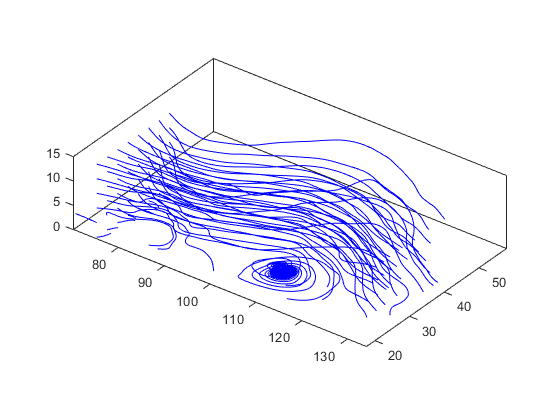

pl.scene_begin('scene_file', 'coneplot.pov', 'image_file', 'coneplot.png');
    pl.include("shapes");    
    pl.include("glass");
    
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    % pl.camera('angle', 30, 'location', [150 150 80], 'look_at', [100 0 0], 'type', 'perspective');
    pl.camera('angle', 30, 'location', [0 0 450], 'look_at', [0 0 0], 'type', 'orthographic');
    
    % Lights
    pl.light('location', [70 70 20],  'color', [10 10 10], 'shadowless', true);
    pl.light('location', [70 70 -20], 'color', [10 10 10], 'shadowless', true);
    pl.light('location', [2 2 2],     'color', [10 10 10], 'shadowless', true);
    
    %%%
    pl.axis('length', [40 40 40]);

    % Wind for streams
    load wind u v w x y z
    [m,n,p] = size(u);
    
    % Bounding box
    tex =  pl.declare("tex", pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.1 0.3 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    pl.wire_box('llf_corner', [80 n*0.5 0], 'urb_corner', [m + 80 n*1.5  p], 'radius', 0.1, 'texture', tex);
    
    % Streamline
    [sx,sy,sz] = meshgrid(75, 0:3:n, 0:3:p);
    % [sx,sy,sz] = meshgrid(80, 20:10:50, 0:5:15);
    % [sx,sy,sz] = meshgrid(1:1:m, 1:1:n, 1:1:p);
    % [sx,sy,sz] = meshgrid(1:5:m, 1:5:n, 1:5:p);

    sl = streamline(x,y,z, u,v,w, sx,sy,sz);
        pl.streamline('data', sl);
    
    % Display preview
    axis tight equal
    view(37,32)
    box on
    colormap(hsv)
    light


pl.scene_end();

#### Rendering and display

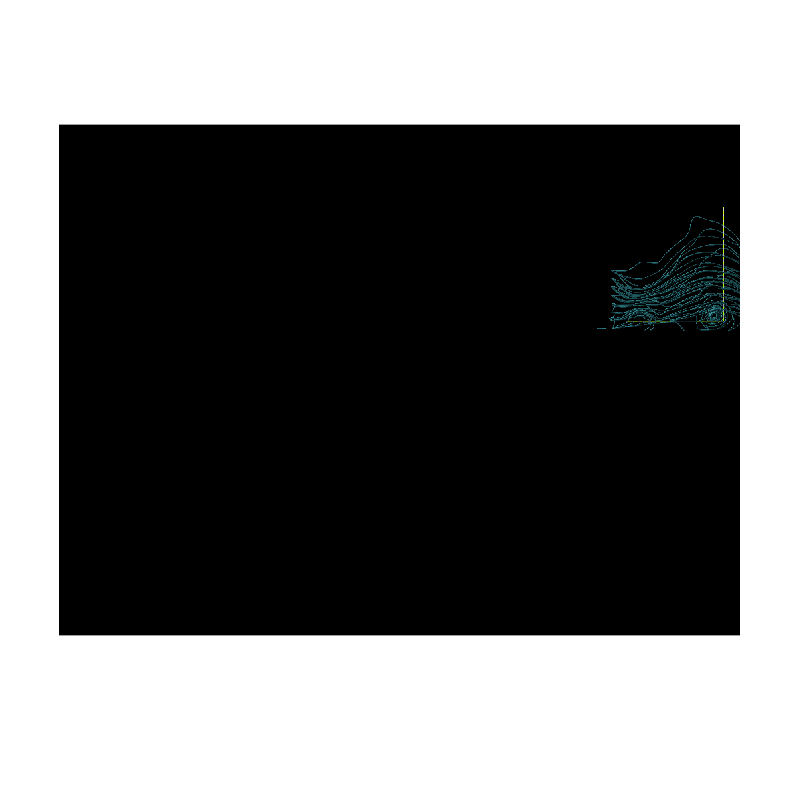

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 6.425633 seconds.
